clear all
close all
clc

f = @(x) x.^2 + 2*x + 3

f = function_handle with value:
    @(x)x.^2+2*x+3


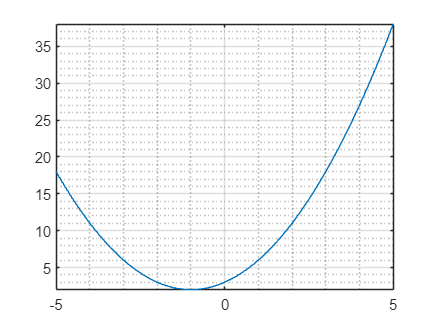

fplot(f);
grid on
grid minor


fzero(f,0)

Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -1.7162e+154 is Inf.)
Check function or try again with a different starting value.


ans = NaN

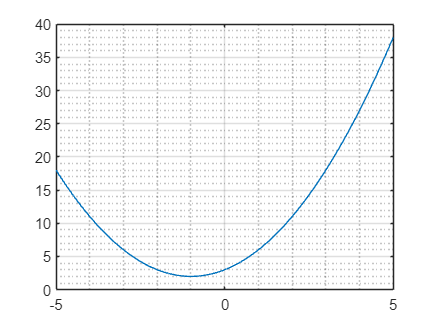


x = linspace(-5,5,100);
a = [1 2 3];

plot(x,polyval(a,x));
grid on 
grid minor


r = roots(a)

r =   -1.0000 + 1.4142i
  -1.0000 - 1.4142i


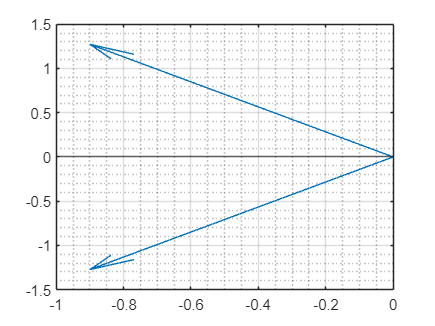

quiver([0 0]',[0 0]',real(r),imag(r))
hold on
xline(0)
yline(0)
grid on 
grid minor

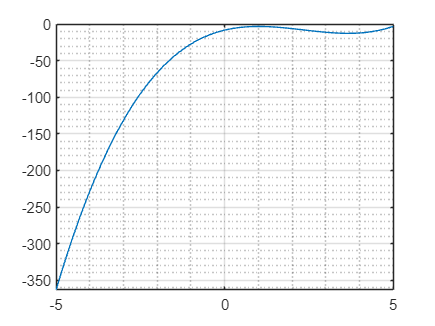

figure();
f = @(x) x.^3 - 7*x.^2+11*x-8;
fplot(f);
grid on
grid minor

a = [1 -7 11 -8]

a =      1    -7    11    -8


r = roots(a)

r =    5.1723 + 0.0000i
   0.9138 + 0.8436i
   0.9138 - 0.8436i


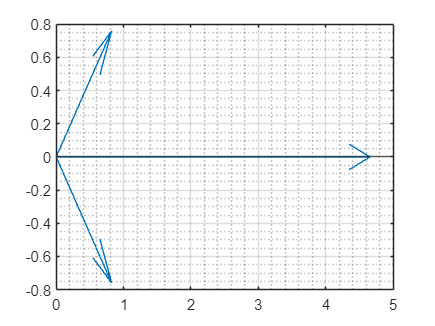

X = zeros(length(r),1);
Y = zeros(length(r),1);
quiver(X,Y,real(r),imag(r))
hold on
xline(0)
yline(0)
grid on 
grid minor

clear all
close all
clc

f = @(a,b,c) (a.^2).*b + (b.^2).*c + (c.^2).*a

f = function_handle with value:
    @(a,b,c)(a.^2).*b+(b.^2).*c+(c.^2).*a


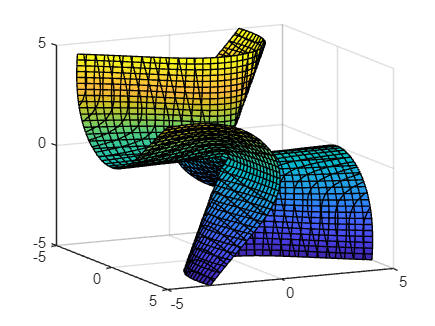

fimplicit3(f)